function g = gdown_RN(r, th, M, Q)
% RN黑洞的下标形式度规
    format long
    
    % 几何因子 f(r)
    f = 1 - 2*M/r + Q^2/r^2;
    
    % 对角矩阵 (4x4)
    g = [-f,    0,    0,    0;
          0,  1/f,    0,    0;
          0,    0,  r^2,    0;
          0,    0,    0,  r^2*sin(th)^2]; 
end

function zamo = localtetrad_RN(metric)
% RN黑洞的局域正交标架
    g11 = metric(1,1);
    g22 = metric(2,2);
    g33 = metric(3,3);
    g44 = metric(4,4);
    
    % e0: 时间方向
    e0 = [1/sqrt(-g11), 0, 0, 0];
    
    % e1: 径向
    e1 = [0, -1/sqrt(g22), 0, 0]; 
    
    % e2: 极角方向
    e2 = [0, 0, 1/sqrt(g33), 0];
    
    % e3: 方位角方向
    e3 = [0, 0, 0, -1/sqrt(g44)];
    
    zamo = [e0; e1; e2; e3];
end

function momentumup = GetRayMomentum_RN(metric, fov, npix, i, j)
% 计算光线在局域标架下的动量，并投影到全局坐标

    format long
    
    % 屏幕坐标映射
    xs = 2*tan(fov/2)/npix * (i - 1/2*(npix+1));
    ys = 2*tan(fov/2)/npix * (j - 1/2*(npix+1));
    
    % 转换角度 
    thx = atan(sqrt(xs^2 + ys^2));
    
    psix = atan2(xs, -ys);
    if psix < 0
        psix = psix + 2*pi;
    end
    
    % 局域光子动量 
    vel = [cos(thx), sin(thx)*cos(psix), sin(thx)*sin(psix)];
    
    % 获取标架
    zamo = localtetrad_RN(metric);
    
    kappa = 1;
    % 投影到全局坐标 (上指标)
    momentumup = ([-kappa, kappa*vel] * zamo)'; 
end

function odefun = geodesic_RN(M, Q)
% 使用符号工具箱生成测地线方程句柄    
    
    syms t r th ph pt pr pth pph tau real
    
    % 构建符号度规
    f_sym = 1 - 2*M/r + Q^2/r^2;
    g_down_sym = diag([-f_sym, 1/f_sym, r^2, r^2*sin(th)^2]);
    g_up_sym = inv(g_down_sym); % 上标度规求逆
    
    % 哈密顿量 H = 0.5 * g^uv * p_u * p_v
    p = [pt; pr; pth; pph];
    Hsyms = 0.5 * p' * g_up_sym * p;
    
    %  哈密顿方程
    % dx/dlambda = dH/dp
    % dp/dlambda = -dH/dx
    vars = [t; r; th; ph; pt; pr; pth; pph];
    
    eqs = [diff(Hsyms, pt);
           diff(Hsyms, pr);
           diff(Hsyms, pth);
           diff(Hsyms, pph);
           -diff(Hsyms, t);
           -diff(Hsyms, r);
           -diff(Hsyms, th);
           -diff(Hsyms, ph)];
           
    
    odefun_sym = matlabFunction(eqs, 'Vars', {tau, vars}); 
    
    odefun = odefun_sym;
end

function II = TraceSingleRay_RN(pos, fov, npix, i, j, M, Q, odefun)
% 单条光线追踪

    format long
    
    % 初值
    metric = gdown_RN(pos(2), pos(3), M, Q);
    momentumup = GetRayMomentum_RN(metric, fov, npix, i, j);
    momentumdown = metric * momentumup; 
    
    initialconditions = [pos; momentumdown];
    
    % 积分长度
    lambdaf = 500; 
    
    % 视界半径估算 
    if M > abs(Q)
        r_horizon = M + sqrt(M^2 - Q^2);
    else
        r_horizon = 0;
    end
    
    % 事件函数：检测落入视界或逃逸
    opts = odeset('Events', @(t,u) myevent(t,u,r_horizon), 'RelTol', 1e-5, 'AbsTol', 1e-6);
    
    [~, ~, ~, ue, ie] = ode45(odefun, [0 lambdaf], initialconditions, opts);
    
    % 上色 
    II = 0; % 默认黑色
    
    if ~isempty(ie)
        last_event = ie(end);
        
        % 事件3: 撞击赤道面 (吸积盘)
        if last_event == 3
            r_hit = ue(end, 2);
            % 简单的吸积盘纹理
             II = Diskvalue(r_hit);
             
        % 事件2: 逃逸 
        elseif last_event == 2
            II = 0.05; % 微弱的背景光
        end
        % 事件1: 落入视界 (保持黑色 II=0)
    end
    
    function [value, isterminal, direction] = myevent(~, u, r_h)
        % u(2) 是 r, u(3) 是 theta
        value = [u(2) - 1.01*r_h;      % 事件1: 落入视界
                 u(2) - 100;           % 事件2: 逃逸
                 u(3) - pi/2];         % 事件3: 撞击赤道面
        isterminal = [1; 1; 1];        % 遇到任何一个都停止 (无限薄盘逻辑)
        direction = [0; 0; 0];
    end

   function val = Diskvalue(r)
        % 环状吸积盘范围: 6M < r < 20M
        if r > 6 && r < 20
             % 基础亮度
             val = 1; 
             
             % 增加同心圆纹理
             val = val * (0.5 + 0.5 * sin(r * 2)^2);
             
             % 距离衰减 (内圈亮，外圈暗)
             val = val * (100 / r^2);
             
             % 限制最大亮度
             val = min(val, 1);
        else
             val = 0;
        end
    end
end

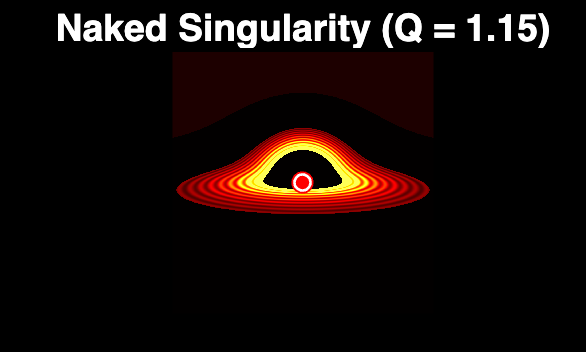

% RN 黑洞演化
clear; clc; clf;

npix = 1500;           % 清晰度
M = 1;
fov = 50* pi / 180;  % 角度 
pos = [0, 50, 80*pi/180, 0]; % 机位

Q_list = 0 : 0.05 : 1.15; 
filename = 'RN_RedDot_Cinema.gif';


% 渲染循环（该板块有参考ai的建议）
for k = 1:length(Q_list)
    Q = Q_list(k);
    
    odefun = geodesic_RN(M, Q); 
    Result = zeros(npix, npix);
    
    % 渲染核心
    for j = 1:npix
        for i = 1:npix
            Result(i, j) = TraceSingleRay_RN(pos', fov, npix, i, j, M, Q, odefun);
        end
    end
    
    Result = rot90(Result); 
    
    %  绘图  
    imagesc(Result);
    colormap('hot');
    clim([0 1.2]); % 锁定亮度范围
    
    axis off equal;
    set(gcf, 'Color', 'k'); 
    hold on;
    
    if M >= abs(Q)
        % 正常黑洞状态
        title(sprintf('Reissner-Nordström (Q = %.2f)', Q), ...
              'Color', [0.9 0.9 0.9], 'FontSize', 14);
    else
        % 裸奇点状态 (Q > M)
        title(sprintf('Naked Singularity (Q = %.2f)', Q), ...
              'Color', 'w', 'FontSize', 14, 'FontWeight', 'bold');
        plot(npix/2+0.5, npix/2+0.5, 'r.', 'MarkerSize', 25);        
        plot(npix/2+0.5, npix/2+0.5, 'wo', 'MarkerSize', 6, 'LineWidth', 1);
    end
    
    hold off;
    drawnow;
    frame = getframe(gcf); 
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    
    if k == 1
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.1);
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.1);
    end
end